## 1. feladat

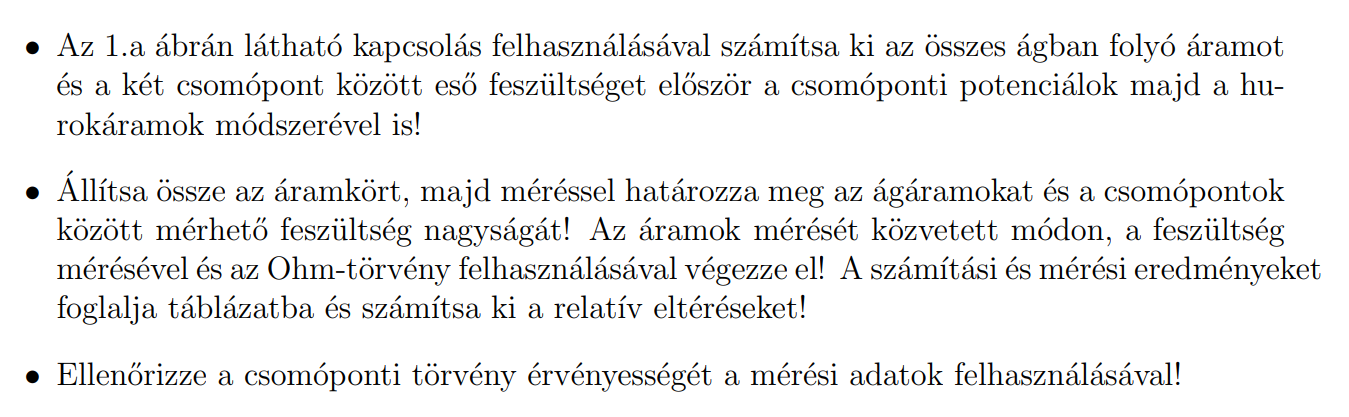

[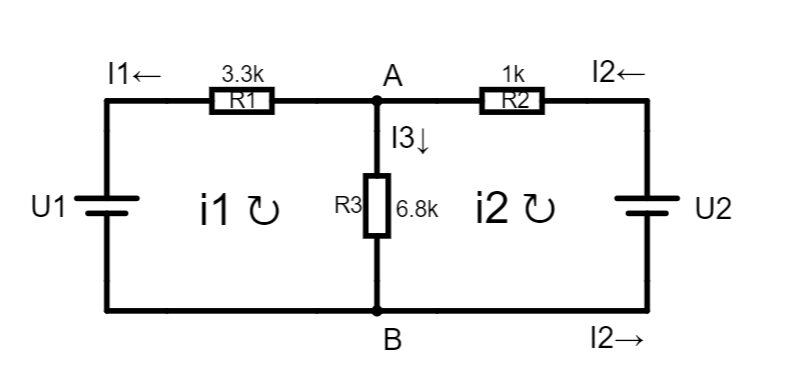](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDu-QcNZoefcVLkKUQlGAhK18oX2SbV4rgYh6QaNGeGD4ki1dVoExI-Zl8muXTc46NZuqWWiDEAtoqwf5WNBFBYDQCFglQ9pEppsmxaYYxFi5ZqVLOrnklDlr25ebVhtpePp7eAUXShTR52h0pDe32vXkDjuIAbiBDEL2ZseA09DMwCGxj5VG1ITQprgvQSwAeIKIozWD6uEjWIABK7AfIWGe6pPTI5+A812hsBwSkKAT6SBmUjId7qK64b7jPAoUg0JgIF7PMGuACqtwsBFByBBh0g2NIEDMaK+d2QSCEMgpaHoxJAAEEoawkCRsc4LMQiShXAAhKFTHHjF6WFEgACSyEACYRQyyuVh8ZzU0F0sVoaVkv7kl4ZAoq3CAZMIZeySB0EBASLTueK0IAkwiZlBxEGIBMo5ogAEtkAAdADOgG7CJmc2H0DD6UiuN0gd1oX0BoA)

### Adatok

U_1 = 3;
U_2 = 6;
R_1 = 3300;
R_2 = 1000;
R_3 = 6800;

### Képletek

$I=\frac{U}{R}$Ohm törvénye

$0=I_1 \pm I_2 +\ldotp \ldotp +I_n$ Kirchhoff csomóponti törvényének formalizált alakja

$V_a -V_b =U_{\textrm{g1}} \pm U_{\textrm{g2}} \pm \ldotp \ldotp \pm U_{\textrm{gn}} \pm I_1 \cdot R_1 \pm \ldotp \ldotp \pm I_n \cdot R_n$ Kirchhoff hurok törvényének formalizált alakja

### Csomóponti

#### Számolás

Első lépés, hogy felírjuk a csomópontokra a csomóponti törvényt. $I_2 =I_1 +I_3$ ($A$ és $B$ pont is azonos)

$V_a -V_b =R_1 \cdot I_1 +U_1$ (balra)

$V_a -V_b =-R_2 \cdot I_2 +U_2$ (jobbra)

$V_a -V_b =R_3 \cdot I_3$(lefele)

Fejezzük ki az I-ket úgy, hogy feltételezzük, hogy $V_b =\emptyset$

$I_1 =\frac{V_a -U_1 }{R_1 }$,$I_2 =-\frac{V_a -U_2 }{R_2 }$,$I_3 =\frac{V_a }{R_3 }$

Csomópontiba behelyettesítünk


$$\begin{array}{l}
\frac{V_a -U_1 }{R_1 }+\frac{V_a }{R_3 }+\frac{V_a -U_2 }{R_2 }=0\\
\frac{V_a }{R_1 }-\frac{U_1 }{R_1 }+\frac{V_a }{R_3 }-\frac{U_2 }{R_2 }+\frac{V_a }{R_2 }=0\\
V_a \left(\frac{1}{R_1 }+\frac{1}{R_3 }+\frac{1}{R_2 }\right)=\frac{U_2 }{R_2 }+\frac{U_1 }{R_1 }\\
V_a =\frac{\frac{U_2 }{R_2 }+\frac{U_1 }{R_1 }}{\frac{1}{R_1 }+\frac{1}{R_3 }+\frac{1}{R_2 }}
\end{array}$$


V_a = ((U_2 / R_2) + (U_1 / R_1)) / ((1/R_1)+(1/R_3)+(1/R_2))

V_a = 4.7646

I_1 = (V_a - U_1) / R_1

I_1 = 5.3473e-04

I_2 = - (V_a - U_2) / R_2

I_2 = 0.0012

I_3 = V_a / R_3

I_3 = 7.0068e-04


$$V_a -V_b =4,76V$$



$$I_1 =0,534\textrm{mA},I_2 =1,2\textrm{mA},I_3 =0,7\textrm{mA}$$


#### Ellenőrzés

[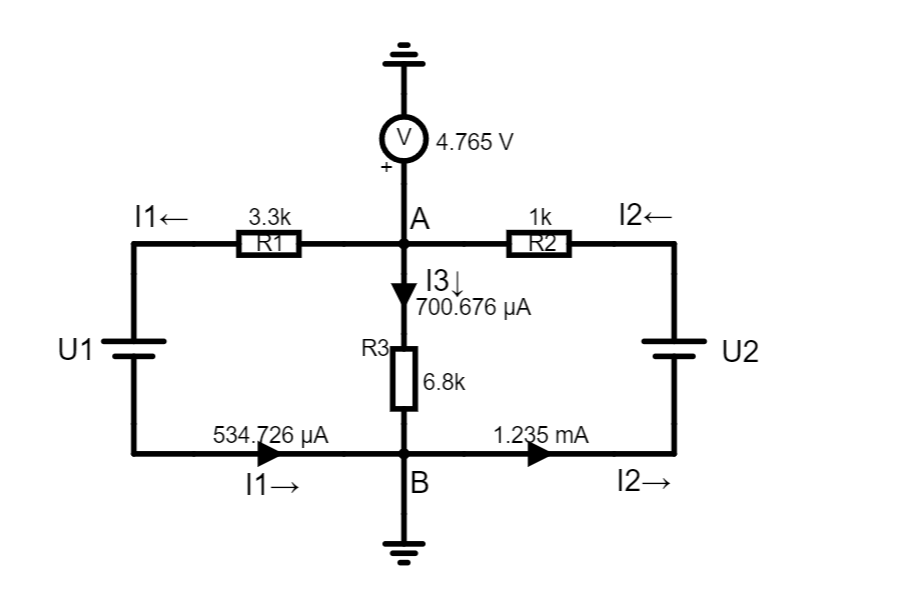](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgjCAMB0l3BWcMBMcUHYMGZIA4UA2ATmIxAUgpABZsKBTAWjDACgAnKcFPEPKmF7dsuSGwDu-QcNYoefcVLkLwQ8DRpRJa+UL5hNq8V0Nb9IFCnPDB8HVZt8UCQsZ0y+TbHtudd4BhuKo7chAJKAaEhNFSRMVQClrHayurWgkYZqZauyVQubqGRhaqlZjnevl4+GlqRBSlV+ZW12c3FbABuIB3WvbUVcbRU9MMwCN25Rf3lRsMpbuPQkwAeIKLgtTQG2Eg2IABK7OtgGLt6xPRge7Q8Ryhs63jE4HgGkObEEAeH2E+9HDgYhUJgIa5XO5gNwAVROljwEDA3w2kCRxC05lhj1OYCQQhk+JQ9CxIAAggDWEgiEiXJZCJjwG4AEIA5qsV7eHjyUkASTAgATCAFWYJgZwIIk-JkgXkoIWnYngcF1JVuPnYQDJhMK6UQCggtEQSdLZYAkwjYAHMohg9Ol3tx4ulrVEUg75MRRdVtAAHALugI7Db2i3+gzqWpxNjYDDDbJJbIQCPrTD0+R5Ij7Y1gM1SUrZULZcRRzIGlL5lIJ7RFgIVFRnYJBoA)

### Hurokáramok


$$i_1 :$$

$$U_1 =\left(R_1 +R_3 \right)\cdot i_1 -R_3 \cdot i_2$$



$$i_2 :$$
 
$$-U_2 =\left(R_2 +R_3 \right)\cdot i_2 -R_3 \cdot i_1$$



$$\begin{array}{l}
I_1 =-i_1 \\
I_2 =-i_2 \\
I_3 =i_1 -i_2 
\end{array}$$



$$\left\lbrack \begin{array}{ccc}
i_1  & i_2  & C\\
R_1 +R_3  & -R_3  & U_1 \\
-R_3  & R_2 +R_3  & -U_2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{ccc}
10100 & -6800 & 3\\
-6800 & 7800 & -6
\end{array}\right\rbrack$$


matrix = [10100 -6800 3; 
    -6800 7800 -6];
matrix1 = matrix;
matrix(1, :) = matrix(1, :) ./ matrix(1, 1); % Első sor egységgé alakítása
matrix2 = matrix;
matrix(2, :) = matrix(2, :) - matrix(1, :) .* (matrix(2, 1) / matrix(1, 1)); % Második sor kinullázása elsővel
matrix3 = matrix;
matrix(2, :) = matrix(2, :) ./ matrix(2, 2); % Második sor egységgé alakítása
matrix4 = matrix;
matrix(1, :) = matrix(1, :) - matrix(2, :) .* (matrix(1, 2) / matrix(2, 2)); % Első sor kinullázása másodikkal
disp(table(matrix1, ["egység"; ""], matrix2, [""; "+(1)*6800"], matrix3, [""; "egység"]))

            matrix1              Var2                   matrix2                    Var4                   matrix3                 Var6  
    _______________________    ________    _________________________________    ___________    _____________________________    ________

    10100    -6800        3    "egység"        1      -0.67327    0.00029703    ""             1      -0.67327    0.00029703    ""      
    -6800     7800       -6    ""          -6800          7800            -6    "+(1)*6800"    0        3221.8       -3.9802    "egység"



disp(table(matrix4, ["+(2)/0.673"; ""], matrix))

               matrix4                   Var2                    matrix             
    _____________________________    ____________    _______________________________

    1      -0.67327    0.00029703    "+(2)/0.673"    1              0    -0.00053473
    0             1    -0.0012354    ""              0              1     -0.0012354



i_1 = matrix(1, 3)

i_1 = -5.3473e-04

i_2 = matrix(2, 3)

i_2 = -0.0012

I_1 = -i_1

I_1 = 5.3473e-04

I_2 = -i_2

I_2 = 0.0012

I_3 = i_1 - i_2

I_3 = 7.0068e-04

## 2. feladat

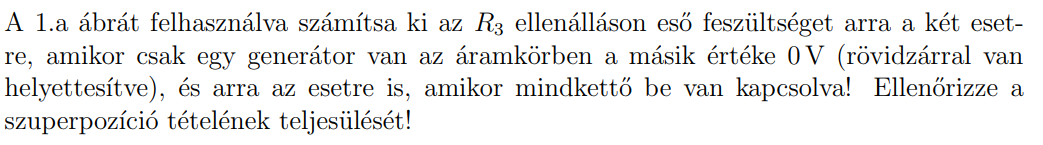

[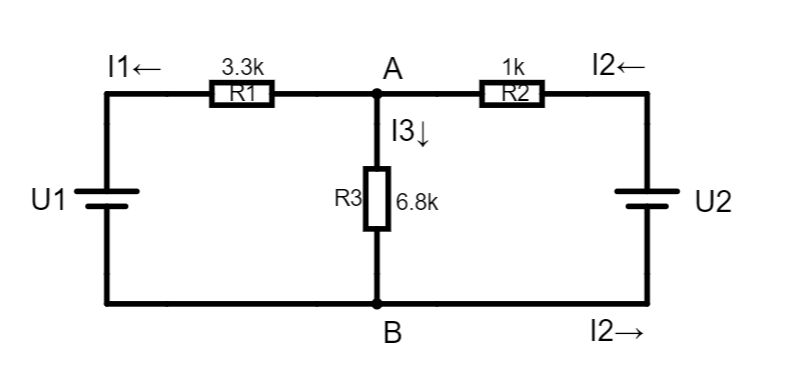](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDu-QcNZoefcVLkKUQlGAhK18oX2SbV4rgYh6QaNGeGD4ki1dVoExI-Zl8muXTc46NZuqWWiDEAtoqwf5WNBFBYDQCFglQ9pEppsmxaYYxFi5ZqVLOrnklDlr25ebVhtpePp7eAUXShTR52h0pDe32vXkDjuIAbiBDEL2ZseA09DMwCGxj5VG1ITQprgvQSwAeIKIozWD6uEjWIABK7AfIWGe6pPTI5+A812hsBwSkKAT6SBmUjId7qK64b7jPAoUg0JgIF7PMGuACqtwsBFByBBh0g2NIEDMaK+d2QSCEMgpaHoxJAAEEoawkCRsc4LMQiShXAAhKFTHHjF6WFEgACSyEACYRQyyuVh8ZzU0F0sVoaVkv7kl4ZAoq3CAZMIZeySB0EBASLTueK0IAkwjYQA)

### Adatok

U_1 = 3;
U_2 = 6;
R_1 = 3300;
R_2 = 1000;
R_3 = 6800;

### Képletek

$I=\frac{U}{R}$Ohm törvénye

### Számolás

#### Csak bal oldali generátor létezik

[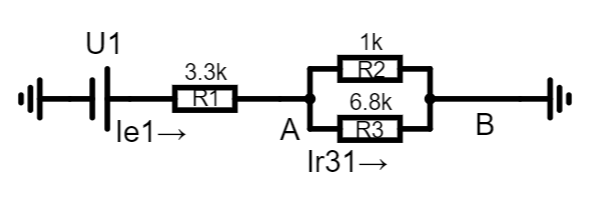](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDuIUsR58ZKMBHFcFrNCmKCh3VHE7TZyJZsEmaxAeIBuIJrg1C+g4TRpga9N1GgI2ADxBRFAdwPmRcJAgdACV2QKFkFGRKCKMMcB4QGLQAnjNSEKRkBA1ojRjcPKY0aMgIJjrKaNkAVXj+QWppLvoWkABBPOQCaLBU0mju-oAhSUNkjTVXeeW+ATkoeeQtRRaXZ23d9VNN8Skdg5AMcJWAcztQpzswW+cth5vNtFqzrcCmOEEEl8CgEBB+gBJBjIQBJhHlJppUrhUlh3JoQJCOLg4WwgA)


$$R_{\textrm{e1}} =R_1 +\left(R_2 ||R_3 \right)=R_1 +\left(\frac{1}{\frac{1}{R_2 }+\frac{1}{R_3 }}\right)=7171,8\Omega$$


R_e1 = R_1 + (1 / ((1 / R_2) + (1 / R_3)))

R_e1 = 4.1718e+03


$$I_{\textrm{e1}} =\frac{U_1 }{R_{\textrm{e1}} }=719,11\cdot {10}^{-6} A$$


I_e1 = U_1 / R_e1

I_e1 = 7.1911e-04

Az $I_{\textrm{e1}}$áramerősség az A csomópontban arányosan oszlik szét.


$$I_{\mathrm{r31}} =I_{\mathrm{e1}} \cdot \frac{R_2 }{R_3 +R_2 }=167,24\mu A$$


I_r31 = I_e1 * (R_2 / (R_3 + R_2))

I_r31 = 9.2194e-05

$U_{\mathrm{r31}} =I_{\mathrm{r31}} \cdot R_3 =$0,6269 V

U_r31 = I_r31 * R_3

U_r31 = 0.6269

#### Csak a jobb oldali generátor létezik

[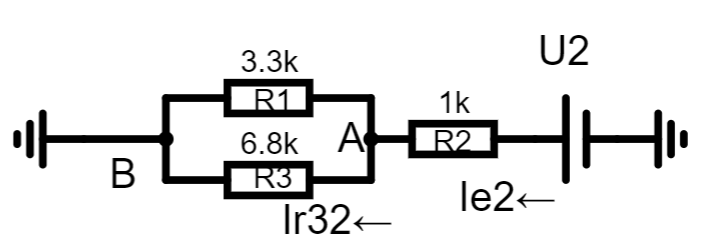](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnEDAkYiNAV78oIXPkiduQkARq4EaWTRqo4Uwb1LFuhENtHE5kgG5iCEOWMXLRNMDR0qo0BGwAe3MErLcElLCUIZCUAJXZPXBDZJFxsWV5gsLQPLyVyP0pUIJQw3FSFegRkMTwqCGCdAFUUz2wkAiRBBsSUHQBBVOQCHQzkA2zwNpAAITYAc3NLezhbFTYAd2leK00+CEkltdWZA0lJ5CwdK2RiGit5rb0DHjnF3RXVI7ur4QE9C4K0JVReXDOUKwhqcQABJBhoQAJhKk0Ah6KxKGgBhhgTpQRw4tCgA)


$$R_{\textrm{e2}} =R_2 +\left(R_1 ||R_3 \right)=R_2 +\frac{1}{\frac{1}{R_1 }+\frac{1}{R_3 }}=3221,8\Omega$$


R_e2 = R_2 + (1 / ((1 / R_1) + (1 / R_3)))

R_e2 = 3.2218e+03


$$I_{\mathrm{e2}} =\frac{U_2 }{R_{\mathrm{e2}} }=1,9\mathrm{mA}$$


I_e2 = U_2 / R_e2

I_e2 = 0.0019

Az $I_{\textrm{ee}}$áramerősség az A csomópontban arányosan oszlik szét.


$$I_{\mathrm{r32}} =I_{\mathrm{e2}} \cdot \frac{R_1 }{R_1 +R_3 }=608,48\mu A$$


I_r32 = I_e2 * (R_1 / (R_1 + R_3))

I_r32 = 6.0848e-04

$U_{\textrm{r32}} =I_{\textrm{r32}} \cdot R_3 =$4,138 V

U_r32 = I_r32 * R_3

U_r32 = 4.1377

#### Tétel bizonyítás

Az első feladatban kiszámoltuk az $R_3$ellenállsára eső feszültséget, ennek értéke $V_a -V_b =4,76\;V$


$$V_a -V_b =U_{\mathrm{r32}} +U_{31}$$


V_a

V_a = 4.7646

U_r32 + U_r31

ans = 4.7646

V_a - (U_r32 + U_r31) < 0.00001

ans = logical
   1


### Ellenőrzés

[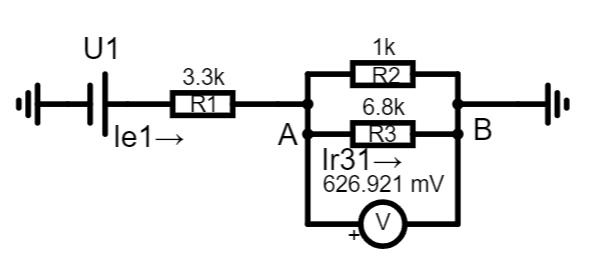](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDuIUsR58ZKMBHFcFrNCiyz13VHE7TtSzUeUhiA8QDcQTXBqF9BwmjTA16rqNARsAHiCiKPbgfMi4SBBCIABK7AHhgsiUyGBIQm48sWj+cophYPTICMjgWTG4uUxoUZAQTLWUUbIAqvH8gtTSnfTNIACCucgEUWAppFFdfQBCkoYo0Wouc0t8AnniUsna0dsbc3uOIBhhywDmtiFHDadOUGwXJ3loNRv3AUxhJYGdEH0AkgxkIAkwiGkCKxCKYG0xFkAI4uBBbAADvNkKQHFoUBjAtxNmjjGocfjDsZDsSDlijqTlGwgA)[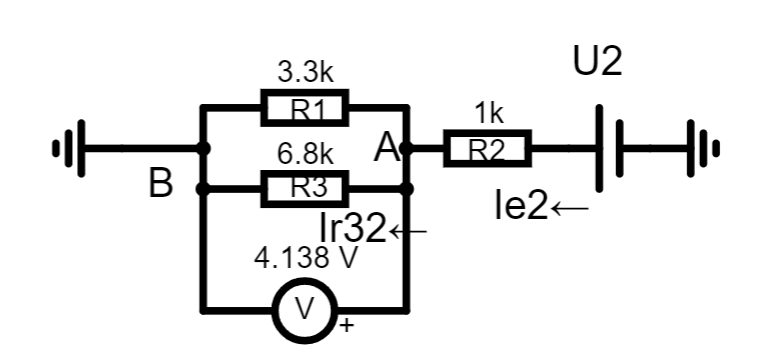](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnEDAkYiNAV78oIXPkiduQkARq4EaWTRqo4Uwb1LFuhENtHE5kgG5iCEOWMXLRNMDR0qo0BGwAe3MErLcElLCUIZCUAJXZPXBDZJFxsWV5gsLQPLyVyP0pUIJQw3FSFegRkMTwqCGCdAFUUz2wkAiRBBsSUHQBBVOQCHQzkA2zwNpAAITYAc3NLezhbFTYAd2leK00+CEkltdWZA0lJ5CwdK2RiGit5rb0DHjnF3RXVI7ur4QE9C4K0JVReXDOUKwhqcQABJBhoQAJhKk0Ah6KxKGgBhhgTpQRw4tCAA7LFBgd68ZD4sR2e63G56IkbMm7HRrKlQNhAA)

[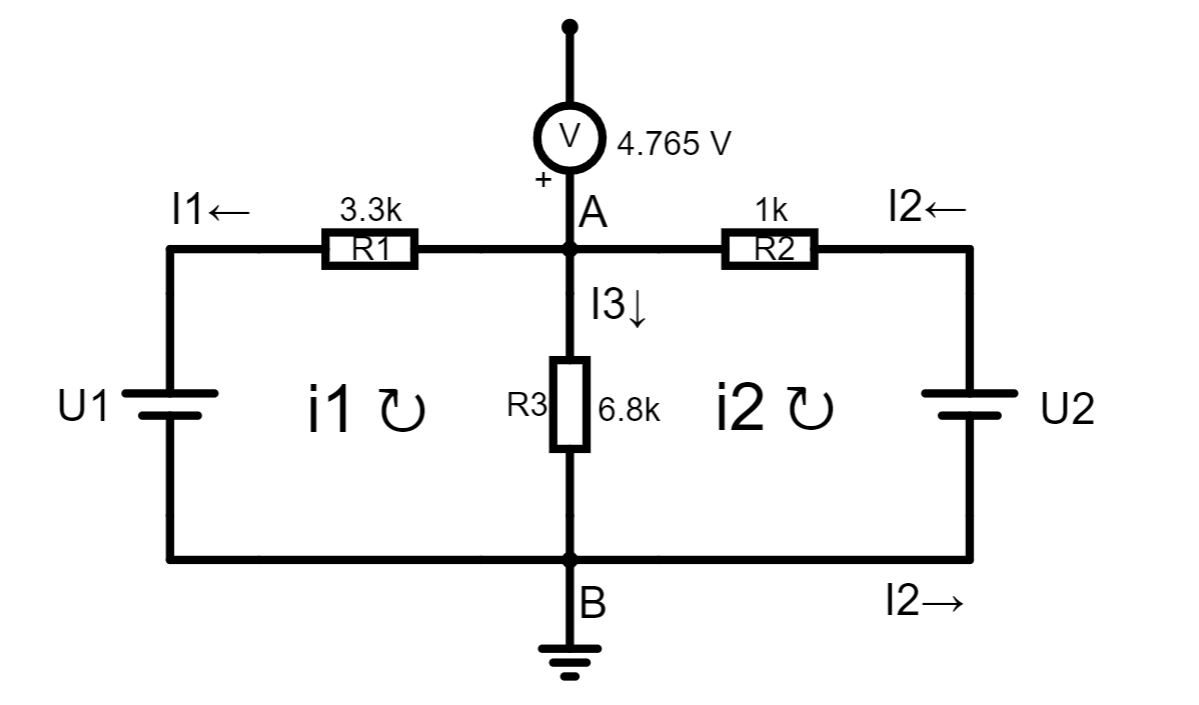](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnKFNAkAmsl7dc+SGwDu-QcNZoefcVLkKUQlGAhK18oX2SbV4rgYh6QaNGeGD4ki1dVoExI-Zl8muXTc46NZuqWWiDEAtoqwf5WNBFBYDQCFglQ9pEppsmxaYYxFi5ZqVLOrnklDlr25ebVhtpePp7eAUXShTR52h0pDe32vXkDjuIAbiBDEL2ZseA09DMwCGxj5VG1ITQprgvQSwAeIKIozWD6uEjWIABK7AfIWGe6pPTI5+A812hsBwSkKAT6SBmUjId7qK64b7jPAoUg0JgIF7PMGuACqtwsBFByBBh0g2NIEDMaK+d2QSCEMgpaHoxJAAEEoawkCRsc4LMQiShXAAhKFTHHjF6WFEgACSyEACYRQyyuVh8ZzU0F0sVoaVkv7kl4ZAoq3CAZMIZeySB0EBASLTueK0IAkwiZlBxEGIBMo5ogAEtkAAdADOgG7CJmc2H0DD6UiuN0gd1oX0BgAO-nMKlOh244gA5tEMkEsPJskA)

## 3. feladat

[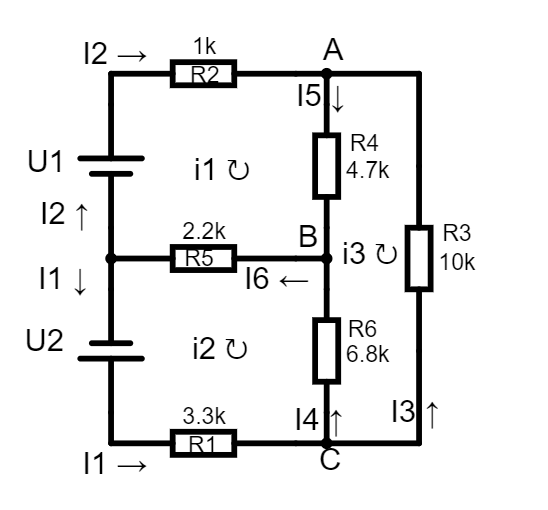](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnEF5NEAmi2L8aNVHE7dWfZFmFCUcqCDQZIknn2x8F25bnzquY0nxpoEwmsQFHlpKymKjwWCVzAEUaL55VoIMXh1AHdwLz0-VUC2MPMsHWRhPVDlFJVLKFi0hPCVXNSxJRMzbKL5JMUrMqrlJNEah2UBLLiRKWEW1L9eXy8u7L8u9vUANyleFFMJrUyXMGtlUWgENnHNJ0FpECb5mnoXGFWADylM5FxkKVxhC4gISoBVdlOWBEpo64-scCcQR7Q2Q2TQ2AzCG3qM1qqQhSgh0xh2wsFUmKTYrzIKFwSCYCyxvj+AEtkAAdADOgG7CdHcNz+Ly4q5oS6-SqEtDkqmnLyyUggXCUZBEFnCQm4DnUph8PD8EBKB7CACCEuQSFkglV0vlIAAQhKID5hB8CLytQBhCW5bCUJjvFQtB58ABKLxpVwIOMyBAJk0dgNOziclCwGpoDpAjtw1MmvHi3noYcdYCjjNkKmSGBZTuIFoeLRtvMF8e84ZOUh+PnppH1pCuWoAkqSyYAkwmVP2D3Crsu9wjr7Ob1IMaauCAixHufzrYrJgETCZVgAsjsvy2sTvuz14qkpl1WkJD1xuAZMJlR9iEhR92QHWwOT1x0dpQC3BhZeEOSj68wPRkNMWCY9xPiHJQAEwjYIA)

### Adatok

R_1 = 3300;
R_2 = 1000;
R_3 = 10000;
R_4 = 4700;
R_5 = 2200;
R_6 = 6800;
U_1 = 3;
U_2 = 6;

### Képletek

$I=\frac{U}{R}$Ohm törvénye

$0=I_1 \pm I_2 +\ldotp \ldotp +I_n$ Kirchhoff csomóponti törvényének formalizált alakja

$V_a -V_b =U_{\textrm{g1}} \pm U_{\textrm{g2}} \pm \ldotp \ldotp \pm U_{\textrm{gn}} \pm I_1 \cdot R_1 \pm \ldotp \ldotp \pm I_n \cdot R_n$ Kirchhoff hurok törvényének formalizált alakja

### Számolás


$$A:$$
 
$$I_2 +I_3 =I_5$$



$$B:$$
 
$$I_5 +I_4 =I_6$$



$$C:$$

$$I_1 =I_4 +I_3$$


Relatív 0V: $U_1$és$U_2$negatív pólusa.


$$i_1 :$$

$$U_1 =\left(R_2 +R_4 +R_5 \right)\cdot i_1 -R_5 \cdot i_2 -R_4 \cdot i_3$$



$$i_2 :$$

$$-U_2 =-R_5 \cdot i_1 +\left(R_1 +R_5 +R_6 \right)\cdot i_2 -R_6 \cdot i_3$$



$$i_3 :$$

$$0=-R_4 \cdot i_1 -R_6 \cdot i_2 +\left(R_3 +R_4 +R_6 \right)\cdot i_3$$



$$\left\lbrack \begin{array}{cccc}
i_1  & i_2  & i_3  & C\\
R_2 +R_4 +R_5  & -R_5  & -R_4  & U_1 \\
-R_5  & R_1 +R_5 +R_6  & -R_6  & -U_2 \\
-R_4  & -R_6  & R_3 +R_4 +R_6  & 0
\end{array}\right\rbrack$$


matrix = [R_2 + R_4 + R_5, -R_5, -R_4, U_1;
    -R_5, R_1+R_5+R_6, -R_6, -U_2;
    -R_4, -R_6, R_3+R_4+R_6, 0]

matrix =         7900       -2200       -4700           3
       -2200       12300       -6800          -6
       -4700       -6800       21500           0


result = rref(matrix)

result =     1.0000         0         0    0.0001
         0    1.0000         0   -0.0005
         0         0    1.0000   -0.0001


i_1 = result(1, 4);
i_2 = result(2, 4);
i_3 = result(3, 4);


$$I_1 =-i_2 ;\;I_2 =i_1 ;I_3 =-i_3 ;I_4 =-i_2 +i_3 ;I_5 =i_1 -i_3 ;I_6 =-i_2 +i_1$$


I_1 = -i_2

I_1 = 5.3735e-04

I_2 = i_1

I_2 = 1.4830e-04

I_3 = -i_3

I_3 = 1.3751e-04

I_4 = -i_2 + i_3

I_4 = 3.9983e-04

I_5 = i_1 - i_3

I_5 = 2.8582e-04

I_6 = -i_2+i_1

I_6 = 6.8565e-04


$$\begin{array}{l}
I_1 =537,35\mu A\\
I_2 =148,3\mu A\\
I_3 =137,51\mu A\\
I_4 =399,8\mu A\\
I_5 =285,82\mu A\\
I_6 =685,6\mu A
\end{array}$$



$$U_b =R_5 \cdot I_6 =1,508V$$


U_b = R_5 * I_6

U_b = 1.5084


$$\begin{array}{l}
U_a -U_b =R_4 \cdot I_5 \\
U_a =R_4 \cdot I_5 +U_b =2,852V
\end{array}$$


U_a = R_4 * I_5 + U_b

U_a = 2.8518


$$\begin{array}{l}
U_c -U_b =R_6 \cdot I_4 \\
U_c =R_6 \cdot I_4 +U_b =4,227V
\end{array}$$


U_c = R_6 * I_4 + U_b

U_c = 4.2273

### Ellenőrzés

[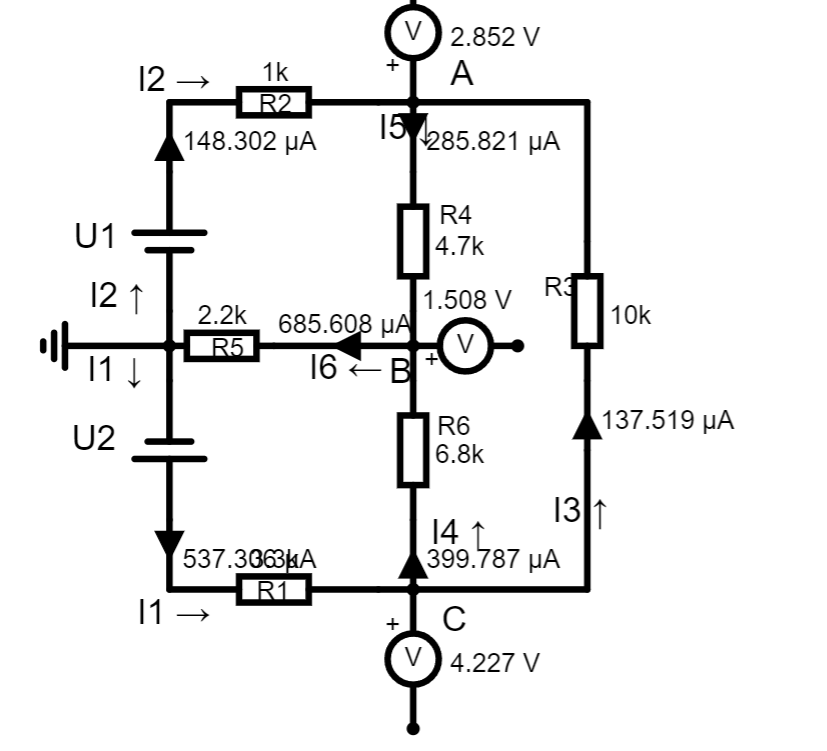](https://www.falstad.com/circuit/circuitjs.html?ctz=CQAgLCAMB0l3BWEBGGAmOaDsWDMkAONANgE5SsQFIrxcqBTAWmWQCgAnEF5NEYiC2L8INVHE7dWfZFmFMBKOVBBoMkSTz5oCBKcJ16aufBq5jSfGmgTCaxAhPMhSdlMRo0wWJyEcodPwsrFHgNAHcg1V0otVE2SOsYoWijBJVDWJiIlVk3ZEsodLFlMQ8ixJF9Kpz-Xj1-RVr7URq2ADcpXhRCrVVbFS97QahoBA6umXK+1xGwYxGYcYAPKQHkXGQpXGENiAhkYQBVdlWWBEo47cvscHcQI7R0vsOaF9Ln6SV5L4KrNlWsioBkoCFId0OIAAggCuj16CwesIDsIAEKwjYgfCXCCbLz3ADCsKYWG0pARF1UswOfAASqduFgtmRuANSRC6U9VuVkAh6FgkLzkQEQLTcBiZBhVJRePQaaKwBitmggSRVFL5bTiMTySgCFsSXpkAR9iLaSspLd8IJSLjIJQUSAAJLIAA6AGdAEmExN4oPBTFt-D4jqdaA93u5EBslAI4JI+MhTtwHsAiYQ+sDg3l6FhoFFbENh91ps684KWwWkJAht3uwDJhLC9CRKCZpQnhE6wKmfcJ9S4-KbEwgPfWzmAjaQDbyegP28QPYAEwjYAHNJt99CU3BpcD5csoFAdlFtPGxtzR-Fc6oUj0VT6vZn1FNetzu+jYft1Mk+TzukkZ+rtBm-TwahcADjwABwybIsQQPh6AglQmhUeCikgjdwCNZQUI0IA)